# Track Monitor Classification Tutorial

Track Monitor classification looks for seven different types of flight behaviors: normal, analyomly, Hobbist One, Hobbist Two, Hobbist Three, Rogue 1, and Rogue 2. 

## Normal Flights

A normal flight path are flights that follow the lane structure and the rules of system. These flights are usually just flights that contain slight noise in the flight trajectory and sensory information. 

This first code segment is used to set up the simulation for the normal flights.

% Set up Simulation Information
lane = LBSD();
lane = lane.genSampleLanes(10, 15);
sim = Sim();
sim.lbsd = lane;
uas_list = [];

% Ensure a successful flight
while(size(uas_list, 2) < 1)
    sim.initialize();
    uas_list = sim.getSuccessfulUAS();
end
uas = uas_list(1);
res = sim.lbsd.getReservations();
minTime = min(res.entry_time_s);
maxTime = max(res.exit_time_s);
num_steps = floor((maxTime - minTime)/sim.step_rate_hz);

% Set up Track Monitor Information
monitor = TrackMonitor;
monitor.initializeLaneStructor(sim.lbsd);

This next code segment is used to show the flight and how the track monitor classifed the given flight with each time step.

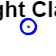

figure;
% Run the simulation
for i = 1:num_steps*2
    tnew = table();
    tnew.ID = "";
    tnew.pos = zeros(1,3);
    tnew.speed = zeros(1,3);
    tnew.time = 0;
    telemetry = tnew;
    radars = tnew;
    index = 1;
    uas_step = uas.stepTrajectory();
    if uas.active
        pos = uas.exec_traj;
        if ~isempty(pos)
            uas.gps.lon = pos(uas_step, 1);
            uas.gps.lat = pos(uas_step, 2);
            uas.gps.alt = pos(uas_step, 3);
            uas.gps.commit();
            traj = uas.exec_traj;
            set(uas.h, 'XData', traj(:,1), ...
                'YData', traj(:,2), ...
                'ZData', traj(:,3));
            sim.step(1);
            telemetry{index, {'ID', 'pos', 'speed', 'time'}} = ...
                [uas.id, [uas.gps.lon, uas.gps.lat, uas.gps.alt], ...
                [uas.gps.vx, uas.gps.vy, uas.gps.vz], 0];
            radars{index, {'ID', 'pos', 'speed', 'time'}} = ...
                [uas.id, [uas.gps.lon + rand()*.1, ...
                uas.gps.lat+rand()*.1, uas.gps.alt+rand()*.1], ...
                [uas.gps.vx + rand()*.1, uas.gps.vy + rand()*.1,...
                uas.gps.vz + rand()*.1], 0];
            monitor.AnalyzeFlights(telemetry, radars, [], 1);
            flightInfo = monitor.flights;
            if(flightInfo.classification(end) == "normal")
                plot3(uas.gps.lon, uas.gps.lat, uas.gps.alt, 'bo');
            else
                plot3(uas.gps.lon, uas.gps.lat, uas.gps.alt, 'r*');
            end
            hold on;
        end
    end
end
title("Normal Flight Classification");
xlabel("North - South")
ylabel("East - West")
hold off;

## Hobbist Two

A hobbist two flight is classified as a flight that starts at a launch vertex, and then will flight in a circular pattern in the upper lane system while halting between switching directions. This first code segment is setting up the flight. 

% Setting up the Hobbist Two Flight


This segment of the code is plotting the flight and how the Track Monitor classifed the flight. 

## Rogue 1

## Hobbist One

## Hobbist Three

## Rogue Two